An implementation of the variational stochastic gradient descent algorithm for noisy gradient evaluations.

Added reflective boundaries to allow constrained optimization 

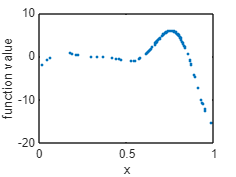

[xx,yy] = optim.AdaptiveGridSampling(@(x) -1*forr(x),0,1,15,4,3);

figure
plot(xx,yy,'.')

xlabel('x')
ylabel('function value')

function [y,dy] = forr(x)

y = ((6*x-2).^2).*sin(12*x-4);
dy =12*(6*x-2).*(sin(12*x-4) + (6*x-2).*cos(12*x-4)) + normrnd(0*x,1);

end